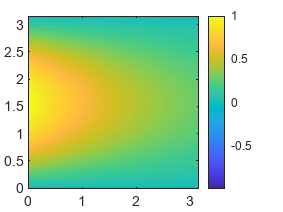

clc, clear; 
close all;

%====grid====%
n = 101;
x = linspace(0,pi,n);
deltax = x(2);
deltat = .9*(deltax^2/2);
t = 0:deltat:pi;
k = .4;

initialTemp = @(x) sin(x);
alp = (deltat*k)/(deltax^2);
u = zeros(length(t),n);
u(1,:) = initialTemp(x); % temperature at time 0 for all x
u(:,n) = 0;
a = alp.*ones(n);
b = -(2*alp+1).*ones(n);
c = alp.*ones(n);
b(1) = 1; c(1) = 0; a(n) = 0; b(n) = 1;
for j = 1:length(t)-1
    d = u(j,:);
    u(j+1,:) = THOMAS3(a,b,c,d,n);
end
imagesc(t,x,u')
set(gca,'Ydir','normal')
colorbar

% supporting function

function x = THOMAS3(a,b,c,d,n)

    %initial condition
    bbar(1) = b(1);
    cbar(1) = c(1);
    dbar(1) = d(1);

    %making upper triangle
    for i = 2:n
        multiplier = a(i)./bbar(i-1);
        abar(i) = a(i) - bbar(i-1).*multiplier;
        bbar(i) = b(i) - cbar(i-1).*multiplier;
        cbar(i) = c(i);
        dbar(i) = d(i) - dbar(i-1).*multiplier;
    end
    
    %initialize x of size n
    x = ones(1,n);

    %initialize end condition
    x(n) = dbar(n)/bbar(n);

    % Upward substitution AKA zip it up
    for i = n-1:-1:1
        x(i) = (dbar(i)-(cbar(i)*x(i+1)))/bbar(i);
    end
end